# # 2024-08-20 - Computer Vision (CV) Posterior Analyses 

addpath(genpath('helpers'));
addpath('External'); % Not recur

should_use_parallel = true;
%should_use_parallel = false;

%img_path = fullfile("E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-28\laps\long_LR\greyscale");
%img_path = fullfile("E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\laps\greyscale"); % old-style
img_path = fullfile("E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale"); % old-style ripples
%img_path = fullfile("/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale");
img_path
imdsTrain = imageDatastore(img_path,'IncludeSubfolders',false);
imdsTrain.readall("UseParallel", should_use_parallel)

img_path = "E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale"

%processed_images = batchposterior_batch_import_imfcn(imdsTrain);
%

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to parallel pool with 8 workers.


ans = 611×1 cell array
    {1024×215 uint8}
    {1024×197 uint8}
    {1024×71  uint8}
    {1024×35  uint8}
    {1024×233 uint8}
    {1024×53  uint8}
    {1024×233 uint8}
    {1024×341 uint8}
    {1024×161 uint8}
    {1024×215 uint8}
    {1024×161 uint8}
    {1024×17  uint8}
    {1024×305 uint8}
    {1024×71  uint8}
    {1024×89  uint8}
    {1024×53  uint8}

imageBatchProcessor(imdsTrain) % shows the GUI

processed_images = batchposterior_batch_import_imfcn(imdsTrain);

PASSED:E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale\p_x_given_n[0].png
PASSED:E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale\p_x_given_n[100].png
PASSED:E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale\p_x_given_n[101].png
PASSED:E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale\p_x_given_n[102].png
PASSED:E:\Dropbox (Personal)\Active\Kamran Diba Lab\Pho-Kamran-Meetings\2024-08-20 - Finalizing Transition Matrix\_temp_individual_posteriors\2024-08-27\ripple\greyscale\p_x_given_n[103].png
PASSED:E:\Dropbox (Personal)\Active\Kamran Diba

## Image Processing Interactive

epoch_idx =7

epoch_idx =      7

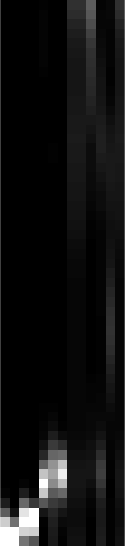

%im = processed_images.seg_bw{epoch_idx};
%info = processed_images.info{epoch_idx};
im = processed_images.imgray{epoch_idx};
% a_shape = size(im)
% 
% lap_sizes = [1024, 449]
% ripple_sizes = [1024, 143]
% 
% lap_to_ripple_size_ratio = ripple_sizes ./ lap_sizes
% 
% % Laps:
% parameters.radius = 4;
% parameters.decomposition = 6;
% parameters.sigma = 59; % You can adjust the sigma value
% % parameters.sigma = [10, 59]; % You can adjust the sigma value
% 
% % Ripples:
% %parameters.radius = 4;
% %parameters.decomposition = 6;
% %parameters.sigma = 59; % You can adjust the sigma value
% % sigma = [10, 59]; % You can adjust the sigma value
% 
% 
% ex_lap_sizes = [1024, 449];
% ex_ripple_sizes = [1024, 143];
% 
% ex_lap_to_ripple_size_ratio = ex_ripple_sizes ./ ex_lap_sizes;
% %ex_lap_to_ripple_size_ratio = [1.0000,	0.3185]
% lap_to_ripple_size_ratio = ex_lap_to_ripple_size_ratio .* a_shape
% 
% 
% % Ripples:
% parameters.radius = round(parameters.radius * min(lap_to_ripple_size_ratio));
% %parameters.decomposition = round(parameters.decomposition * min(lap_to_ripple_size_ratio));
% parameters.sigma = parameters.sigma * min(lap_to_ripple_size_ratio);
% %parameters.sigma = round(parameters.sigma * min(lap_to_ripple_size_ratio));
% parameters
% 
% [processed_images.seg_bw{epoch_idx}, processed_images.seg_maskedImage{epoch_idx}, processed_images.blurredImg{epoch_idx}] = fn_segimg_replay_connect(im, parameters.sigma, parameters.radius, parameters.decomposition);

bw = processed_images.seg_bw{epoch_idx};
blurredImg = processed_images.blurredImg{epoch_idx};
BW = processed_images.seg_bw{epoch_idx};
maskedImage = processed_images.seg_maskedImage{epoch_idx};
E = processed_images.E(epoch_idx,1);
%processed_images = mergevars(processed_images, {'l','m00','m01','m02','m10','m11','m20'}, 'NewVariableName', 'l_m00_m01_m02_m10_m11_m20', 'MergeAsTable', false);
l = processed_images.l(epoch_idx);
m00 = processed_images.m00(epoch_idx);
m01 = processed_images.m01(epoch_idx);
m02 = processed_images.m02(epoch_idx);
m10 = processed_images.m10(epoch_idx);
m11 = processed_images.m11(epoch_idx);
m20 = processed_images.m20(epoch_idx);
w = processed_images.w(epoch_idx);
x = processed_images.x(epoch_idx);
x1 = processed_images.x1(epoch_idx);
x2 = processed_images.x2(epoch_idx);
y = processed_images.y(epoch_idx);
y1 = processed_images.y1(epoch_idx);
y2 = processed_images.y2(epoch_idx);
theta = processed_images.theta(epoch_idx);


%[BW, blurredImg, maskedImage] = fn_segimg_replay_connect(im);

figure(1); imshow(im);

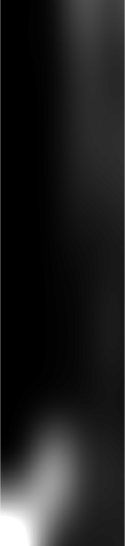

figure(2); imshow(blurredImg);

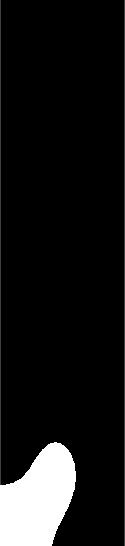

%figure(3); imshow(bw);
figure(3); imshow(BW);

%figure; imshow(maskedImage);

% imP = ImToPolar(im, 0.6, 1, 40, 200);
% figure(2); imshow(imP);
% imR = PolarToIm(imP, 0.6, 1, 250, 250);
% figure(3); imshow(imR);
% rMin = 0.25; rMax = 0.8;

% Rotation invariant image moments
%moment(im)
inv_moments = Hu_Moments(blurredImg)

inv_moments = 1×7 uint8 row vector
   0   0   0   0   0   0   0


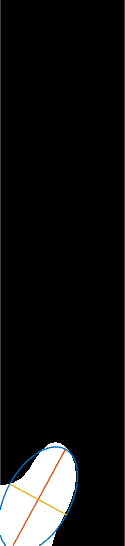

%eta = SI_Moment(blurredImg, BW)
%cen_mmt = Centr_Moment(blurredImg, BW, 1, 1)
%F = IMOMENTS(im)

% https://raphael.candelier.fr/?blog=Image%20Moments

%E = IM.get_ellipse(BW)                % Compute the equivalent ellipse
% Draw the ellipse overlaying the image:
figure; imshow(BW)
hold on
IM.draw_ellipse(E, 'elements', {'ellipse','major','minor','semimajor','direction'}) % , 'color', 'm'

% expand the .E struct for each row of the table
% E_stack = [];
% for i = 1:size(processed_images, 1)
%     E = processed_images.E(i,1);
%     %processed_images
%     E_stack = [E_stack; struct2table(E)];
% end

baseNames = processed_images.baseName;
% Use regexp to extract numbers within brackets
epoch_idx = regexp(baseNames, '\[(\d+)\]', 'tokens');

% Convert extracted cell array of tokens to numeric array
epoch_idx = cellfun(@(x) str2double(x{1}), epoch_idx)

epoch_idx =      0
   100
   101
   102
   103
   104
   105
   106
   107
   108


processed_images.epoch_idx = epoch_idx;


function displayProcessedImagesUI(processed_images)
    row_height = 125;
    col_width = 150;
    % Create a uifigure
    fig = uifigure('Name', 'Processed Images and Data', 'Position', [100 100 600 2200]);

    % Create a main scrollable panel
    scrollPanel = uipanel(fig, 'Scrollable', 'on', 'Position', [20 20 560 2260]);

    % Create a grid layout within the panel
    %grid = uigridlayout(scrollPanel, [height(processed_images), 2], 'ColumnWidth', {200, '1x'}, 'RowHeight', repmat({'fit'}, 1, height(processed_images)));
    %grid = uigridlayout(scrollPanel, [height(processed_images), 2], 'ColumnWidth', {col_width, '1x'}, 'RowHeight', repmat([row_height], 1, height(processed_images)));
    grid = uigridlayout(scrollPanel, [height(processed_images), 3], 'ColumnWidth', {col_width, '1x', '1x'}, 'RowHeight', repmat([row_height], 1, height(processed_images)));
    

    grid.Padding = [5 5 5 5];
    grid.RowSpacing = 10;
    grid.ColumnSpacing = 10;

    % Populate the grid with images and corresponding data
    for i = 1:height(processed_images)
        % Display the image
        img = processed_images.seg_maskedImage{i};
        [imgHeight, imgWidth, ~] = size(img);
        aspectRatio = imgWidth / imgHeight;

        ax = uiaxes(grid);
        ax.Layout.Row = i;
        ax.Layout.Column = 1;

        % Constrain the axes to prevent expansion
        ax.PositionConstraint = 'innerposition';
        ax.XTick = [];
        ax.YTick = [];
        ax.Box = 'on';

        % Display the image and adjust the axis size to fit the fixed width
        fixedWidth = col_width; % Fixed width for the image column
        adjustedHeight = fixedWidth / aspectRatio; % Adjust height based on the image aspect ratio
        %ax.Position(3) = fixedWidth; % Apply fixed width
        %ax.Position(4) = adjustedHeight; % Apply adjusted height
        imshow(img, 'Parent', ax);

        % Display the corresponding numeric data
        dataStr = sprintf('m00: %.2f\nm01: %.2f\nm02: %.2f\nm10: %.2f\nm11: %.2f\nm20: %.2f', ...
            processed_images.m00(i), processed_images.m01(i), processed_images.m02(i), processed_images.m10(i), processed_images.m11(i), processed_images.m20(i));
        uitext = uitextarea(grid, 'Value', dataStr, 'Editable', 'off');
        uitext.Layout.Row = i;
        uitext.Layout.Column = 2;
        uitext.FontSize = 10;

        % Display the additional numeric data (second column)
        dataStr2 = sprintf('x: %.2f\ny: %.2f\ntheta: %.2f\nw: %.2f\nl: %.2f\nx1: %.2f\ny1: %.2f\nx2: %.2f\ny2: %.2f', ...
            processed_images.x(i), processed_images.y(i), processed_images.theta(i), processed_images.w(i), processed_images.l(i), ...
            processed_images.x1(i), processed_images.y1(i), processed_images.x2(i), processed_images.y2(i));
        uitext2 = uitextarea(grid, 'Value', dataStr2, 'Editable', 'off');
        uitext2.Layout.Row = i;
        uitext2.Layout.Column = 3;
        uitext2.FontSize = 10;

    end

    % Adjust the figure to allow resizing
    %fig.SizeChangedFcn = @(src, event) adjustLayout(grid, processed_images);
end

% function adjustLayout(grid, processed_images)
%     % Enforce consistent layout during window resizing
%     for i = 1:height(processed_images)
%         ax = grid.Children(2 * (height(processed_images) - i) + 1); % Get the corresponding axis for each image
%         img = processed_images.seg_maskedImage{i};
%         [imgHeight, imgWidth, ~] = size(img);
%         aspectRatio = imgWidth / imgHeight;
%         fixedWidth = 200; % Re-apply fixed width
%         adjustedHeight = fixedWidth / aspectRatio; % Recalculate height based on aspect ratio
%         ax.Position(3) = fixedWidth;
%         ax.Position(4) = adjustedHeight;
%     end
% end




% Assuming you have a table named processed_images
displayProcessedImagesUI(processed_images);

### Post-hoc Processing of processed_images

D = bwdist(~bw);
figure(); imshow(D,[])
title('Distance Transform of Binary Image')

D = -D;
figure(); imshow(D,[])
title('Complement of Distance Transform')

L = watershed(D);
L(~bw) = 0;
rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb)
title('Watershed Transform')

% Read the sample image in
im = imgray{1}; % imread('shapessm.jpg');
im


% Find edges using the Canny operator with hysteresis thresholds of 0.1
% and 0.2 with smoothing parameter sigma set to 1.
edgeim = edge(im,'canny', [0.1 0.2], 1);

figure(1), imshow(edgeim);

% Link edge pixels together into lists of sequential edge points, one
% list for each edge contour. A contour/edgelist starts/stops at an 
% ending or a junction with another contour/edgelist.
% Here we discard contours less than 10 pixels long.

[edgelist, labelededgeim] = edgelink(edgeim, 10);

% Display the edgelists with random colours for each distinct edge 
% in figure 2

drawedgelist(edgelist, size(im), 1, 'rand', 2); axis off  

% Fit line segments to the edgelists
tol = 2;         % Line segments are fitted with maximum deviation from
	     % original edge of 2 pixels.
seglist = lineseg(edgelist, tol);

% Draw the fitted line segments stored in seglist in figure window 3 with
% a linewidth of 2 and random colours
drawedgelist(seglist, size(im), 2, 'rand', 3); axis off


S = fastradial(im, [1 3 5], 2, 0)

# Mean square displacement analysis of particle trajectories

% ma = msdanalyzer(2, 'µm', 's')

# Tracking

% SPACE_UNITS = 'µm';
% TIME_UNITS = 's';
% 
% N_PARTICLES = 1;
% N_TIME_STEPS = 1861;
% %N_DIM = 2; % 2D
% N_DIM = 1; % 1D
% 
% % Typical values taken from studies of proteins diffusing in membranes:
% % Diffusion coefficient
% D  = 1e-3; % µm^2/s
% % Time step between acquisition; fast acquisition!
% dT = 0.05; % s,
% 
% % Area size, just used to disperse particles in 2D. Has no impact on
% % analysis.
% SIZE = 2; % µm
% k = sqrt(2 * D * dT);

% tracks = cell(N_PARTICLES, 1);
% 
% for i = 1 : N_PARTICLES
% 
%     % Time
%     time = (0 : N_TIME_STEPS-1)' * dT;
% 
%     % Initial position
%     X0 = SIZE .* rand(1, N_DIM);
% 
%     % Integrate uncorrelated displacement
%     dX = k * randn(N_TIME_STEPS, N_DIM);
%     dX(1, :) = X0;
%     X = cumsum(dX, 1);
% 
%     size(time)
%     size(X)
%     % Store
%     tracks{i} = [time X];
% 
% end
% clear i X dX time X0

% tracks = cell(N_PARTICLES, 1);
% tracks{1} = flat_tracks;

% ma = msdanalyzer(N_DIM, SPACE_UNITS, TIME_UNITS);
% % This does not work:
% %ma.addAll(tracks);
% 
% % This works:
% ma = ma.addAll(tracks);
% 
% % Indeed:
% disp(ma)